LAB EXERCISE - 3

BL.AI.U4AID25064

S.Sudarshan Rao

%question 1 
%(a)
A1=randi([0,4],9);
A1pin=pinv(A1);
A1in=inv(A1);
disp("Hence verified")

Hence verified



%(b)
B1=randi([0,4],5,4);
B1pin=pinv(B1);
B1lin=inv(B1'*B1)*B1';
B1lin*B1;
B1pin*B1;
disp("Hence verified")

Hence verified



%(c)
C1=randi([0,4],3,7);
C1pin=pinv(C1);
C1rin=C1'*inv(C1*C1');
C1*C1pin;
C1*C1rin;
disp("Hence verified")

Hence verified


%question 2 - (i)
%(a)
A2=[3 1 -1;1 2 0;0 1 2; 1 1 -1];
v1=[-3 -3 8 9]';
rA2=rank(A2);
p1=A2*inv(A2'*A2)*A2'*v1;
disp("Projection Determined")

Projection Determined



%(b)
B2=[1 1;1 2 ;0 1];
v2=[2 1 3]';
rB2=rank(B2);
p2=B2*inv(B2'*B2)*B2'*v2;
disp("Projection Determined")

Projection Determined



%(c)
C2=[1 1 2 4;1 2 3 6;0 1 1 2];
v3=[2 1 3]';
rC2=rank(C2);
[RR,ic]=rref(C2);
CS2=C2(:,ic);
p3=CS2*inv(CS2'*CS2)*CS2'*v3;
disp("Projection Determined")

Projection Determined


%question 2 - (ii)
%(a)
A3=[1 4 5 6 9;3 -2 1 4 -1;-1 0 -1 -2 -1;2 3 5 7 8];
rank(A3);
disp("R(A3)=2[<m & <n], hence there exits only pseudo inverse for the matrix")

R(A3)=2[<m & <n], hence there exits only pseudo inverse for the matrix


A3pin=pinv(A3)

%(b)
B3=[3 4;1 8];
rank(B3);
disp("As B3 is a 2 by 2 matrix with det!=0, hence inverse exits!")

As B3 is a 2 by 2 matrix with det!=0, hence inverse exits!


B3in=inv(B3);
B3pin=pinv(B3)

%(c)
C3=[0 1 0;0 0 1;0 4 2];
rank(C3);
disp("As rank(C3)=2[<n], therefore there exits only pseudo inverse for the matrix")

As rank(C3)=2[<n], therefore there exits only pseudo inverse for the matrix


C3pin=pinv(C3)

%(d)
D3=[1 2 0 1;0 1 1 0;2 4 0 2];
rank(D3);
disp("As rank(D3)=2[<n & <m], therefore there exits only pseudo inverse for the matrix")

As rank(D3)=2[<n & <m], therefore there exits only pseudo inverse for the matrix


D3pin=pinv(D3)

%(e)
E3=[0 1 4 1;0 0 8 1;0 1 4 0;1 0 8 0;0 1 1 0;1 0 1 0];
rank(E3);
disp("As rank(E3)=4[=n], hence left inverse exits for this matrix")

As rank(E3)=4[=n], hence left inverse exits for this matrix


E3lin=inv(E3'*E3)*E3';
E3pin=pinv(E3)

%question 3 
%(a)
coeff1=[1 1;2 1;3 1; 4 1;5 1];
rank(coeff1);
disp("As rank(coeff1)=2[=n], hence left inverse of the matrix exists.")

As rank(coeff1)=2[=n], hence left inverse of the matrix exists.


const1=[10 10 16 27 23]';
sol1=inv(coeff1'*coeff1)*coeff1'*const1;
disp("sol1 is the required least square approximation")

sol1 is the required least square approximation



%(b)
coeff2=[2 -3 1;1 3 -4;3 -2 -1;5 -1 -4];
const2=[1 -4 -1 -4]';
rank(coeff2);
disp("As rank(coeff2)=2[<m & <n], hence there exists only pseudo inverse for the matirx")

As rank(coeff2)=2[<m & <n], hence there exists only pseudo inverse for the matirx


sol2=pinv(coeff2)*const2;
disp("sol2 is the required least square approximation.")

sol2 is the required least square approximation.



%(c)
coeff3=[2 1;2 -3;3 1;4 1];
const3=[20 4 28 36]';
rank(coeff3);
disp("As rank(coeff3)=2[=n], hence left inverse for the matrix exits")

As rank(coeff3)=2[=n], hence left inverse for the matrix exits


sol3=inv(coeff3'*coeff3)*coeff3'*const3;
disp("sol3 is the required least square approximation solution")

sol3 is the required least square approximation solution


% question - 3 parabola part
coeff4=[4 -2 1;1 -1 1;0 0 1;1 1 1;4 2 1];
const4=[0 0 1 0 0]';
rank(coeff4);
sol4=inv(coeff4'*coeff4)*coeff4'*const4;
disp("sol4 is the required coefficients of the parabola equation")

%question 4
A4=[1 1;1 2;1 4];
b4=[5 6 7]';
rank(A4);
solF_L=inv(A4'*A4)*A4'*b4;
disp("Normal length(a)=4.5 is the acquired solution by least square approximation")

% question 5
A5=[1 -2;1 -1;1 0;1 2];
b5=[4 3 1 0]';
rank(A5);
sol5=inv(A5'*A5)*A5'*b5;
disp("sol5 contains coefficients of the required best straight line")
p5=A5*inv(A5'*A5)*A5'*b5;
disp("p5 is the required projection of b onto column space of A")

% question 6
A6=[-3 1;-2 1;-1 1; 0 1; 1 1; 2 1;3 1];
b6=[4 2 0 0 -2 -2 -3]';
sol6=inv(A6'*A6)*A6'*b6;
disp("sol6 is the required solution of the best possible straight line using least square approximation.")

%question 7
[B,text]=xlsread('C:\Users\exam\Desktop\matlab\xlformatlab.xlsx');
x=B(:,1);
y=B(:,2);
n=length(x);
ATA=[sum(x.^2),sum(x);sum(x),n]

ATA =    770     0
     0    21


ATb=[sum(x.*y);sum(y)]

ATb = 1.0e+04 *

    1.4416
    0.1423


m_and_c= inv(ATA)*ATb

m_and_c =    18.7226
   67.7393


[B,text]=xlsread('C:\Users\exam\Desktop\matlab\xlformatlab.xlsx');
x=B(:,1);
y=B(:,2);
n=length(x);
A=[x,ones(n,1)];
ATA=[sum(x.^2),sum(x);sum(x),n]

ATA =    770     0
     0    21


ATb=[sum(x.*y);sum(y)]

ATb = 1.0e+04 *

    1.4416
    0.1423


m_and_c= inv(ATA)*ATb

m_and_c =    18.7226
   67.7393


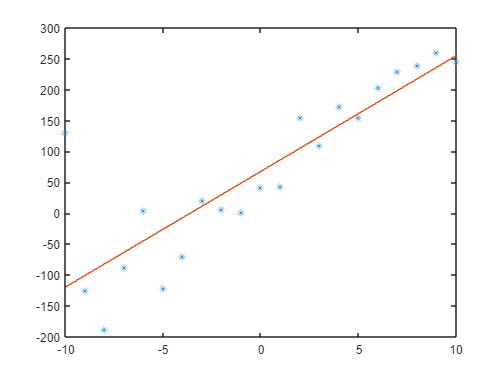

y_projected=A*inv(ATA)*ATb;
plot(x,y,'*')
hold on
plot(x,y_projected)  

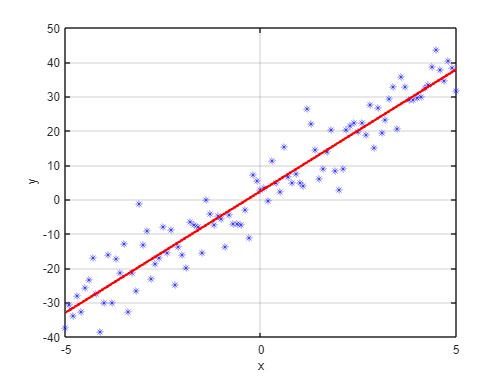

% question 8 
m = 7;
c = 3;

x = -5:0.1:5;
n = length(x);

y = m*x + c;

noise_stdev = 6;
noise = noise_stdev * randn(1, n);

yn = y + noise;

figure
plot(x, yn, 'b*')      
hold on
grid on

A = [x' ones(n,1)];
yn = yn';

m_and_c = pinv(A) * yn;

y_projected = A * m_and_c;

plot(x, y_projected, 'r', 'LineWidth', 2)  

xlabel('x')
ylabel('y')
xlim([-5 5])